% Define the data for lower limit, upper limit, and frequency
lowerLimits = [7.5,10.5,13.5,16.5,19.5,22.5,25.5]; 
upperLimits = [10.5,13.5,16.5,19.5,22.5,25.5,28.5]; 
frequencies = [1,4,7,23,19,9,5];  

% Create a table in MATLAB
dataTable = table(lowerLimits', upperLimits', frequencies',...
    'VariableNames', {'LowerLimit', 'UpperLimit', 'Frequency'});

% Display the table
disp(dataTable);

    LowerLimit    UpperLimit    Frequency
    __________    __________    _________

        7.5          10.5           1    
       10.5          13.5           4    
       13.5          16.5           7    
       16.5          19.5          23    
       19.5          22.5          19    
       22.5          25.5           9    
       25.5          28.5           5    




% Calculate mean, median, mode, and standard deviation
data = [];
for i = 1:length(lowerLimits)
    data = [data, ones(1, frequencies(i)) * ((upperLimits(i) + lowerLimits(i)) / 2)];
end

meanValue = mean(data);
medianValue = median(data);
modeValue = mode(data);
stdDeviation = std(data);

% Calculate empirical_mode, mode_shift, and Karl
empirical_mode = 3 * medianValue - 2 * meanValue;
mode_shift = modeValue - empirical_mode;
Karl = (meanValue - modeValue) / stdDeviation;

% Display the calculated statistics
fprintf('Mean: %.2f\n', meanValue);

Mean: 19.50


fprintf('Median: %.2f\n', medianValue);

Median: 18.00


fprintf('Mode: %.2f\n', modeValue);

Mode: 18.00


fprintf('Standard Deviation: %.2f\n', stdDeviation);

Standard Deviation: 3.93


fprintf('Empirical Mode: %.2f\n', empirical_mode);

Empirical Mode: 15.00


fprintf('Mode Shift: %.2f\n', mode_shift);

Mode Shift: 3.00


fprintf('Karl: %.2f\n', Karl);

Karl: 0.38


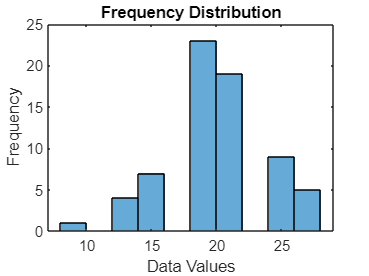


% Plotting the line graph
figure;
histogram(data, 'BinWidth', 2); % Change the 'BinWidth' according to your preference
title('Frequency Distribution');
xlabel('Data Values');
ylabel('Frequency');